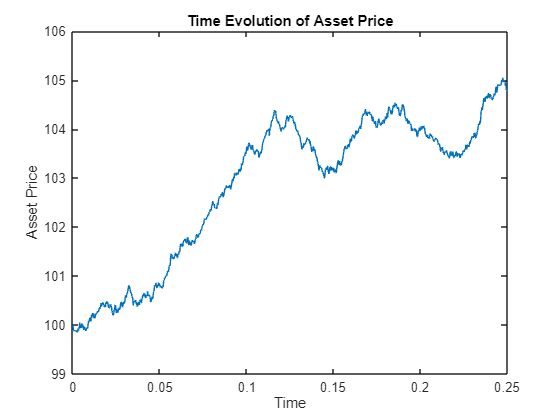

S0 = 100; T = 3/12; n = 1000; mu = .07; sigma = .03;
[tValues,SValues] = geometric_brownian_motion(S0,T,n,mu,sigma);

figure
plot(tValues,SValues)
xlabel('Time')
ylabel('Asset Price')
title('Time Evolution of Asset Price')

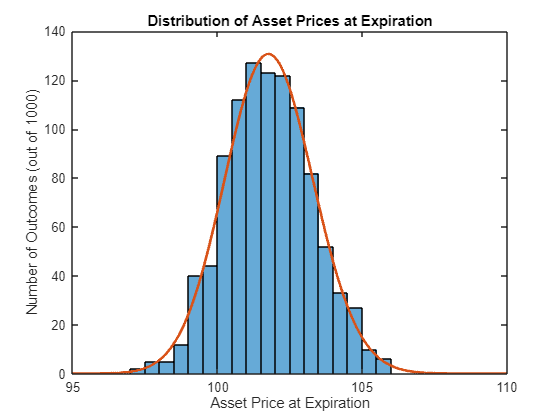


% Looking at the End Results
num_trials = 1000;
final_asset_prices = nan(1,num_trials);
for index = 1:num_trials
    [~,SValues] = geometric_brownian_motion(S0,T,n,mu,sigma);
    final_asset_prices(index) = SValues(end);
end

h = histogram(final_asset_prices);
hold on

S_mesh = 95:.01:110;
prob_density = @(S) exp(-power(log(S/S0)-(mu+sigma^2/2)*T,2)/2/(sigma*sqrt(T))^2)/sqrt(2*pi)/(sigma*sqrt(T))./S;
plot(S_mesh,num_trials*h.BinWidth*prob_density(S_mesh),'LineWidth',2)
xlabel('Asset Price at Expiration')
ylabel('Number of Outcomes (out of 1000)')
title('Distribution of Asset Prices at Expiration')


% Normalization Check
assert(abs(integral(prob_density,0,200)-1) < 1e-6)


delta = find_delta(100,100,.05,.2,1/12)

delta = 0.4598